*Tratamiento de imagen*

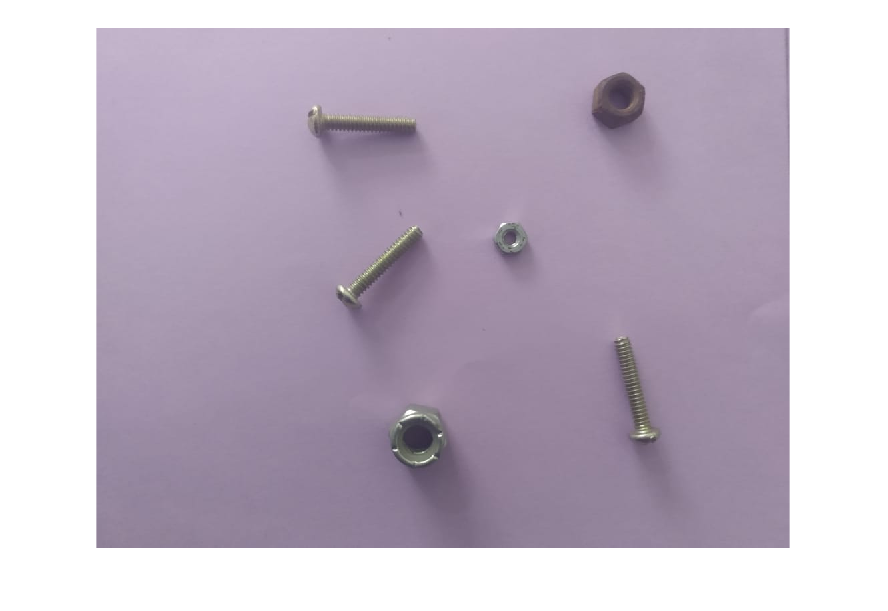

clear all

im = imread("I6.jpeg"); % lectura de la imagen
imshow(im)

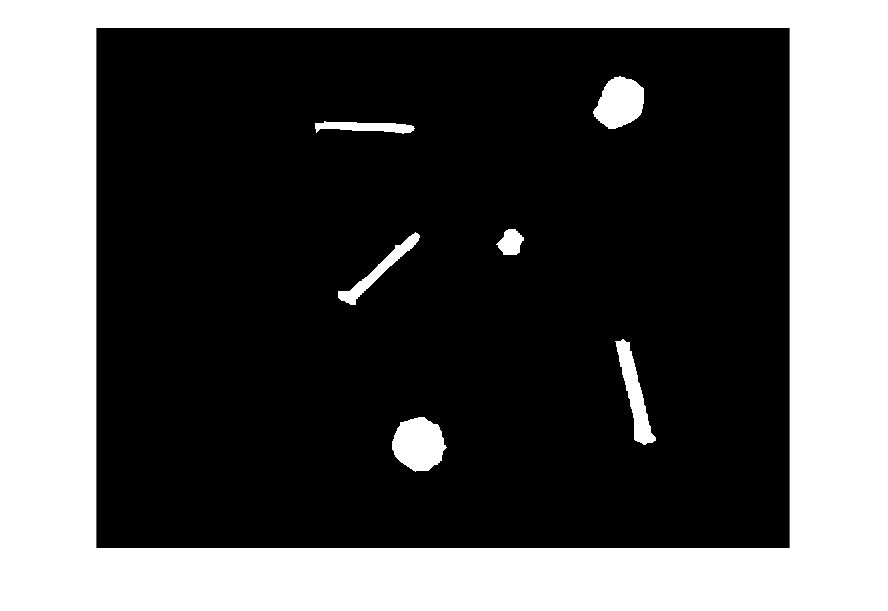


g = im(:,:,3); % Se pasa la imagen a escala de gris
%imshow(g)

d = size(g); % Tamaño de la imagen

% Umbralizacion
for i = 1:d(1)
    for j = 1:d(2)
        if g(i,j) > 100
            t(i,j) = 0;
        else
            t(i,j) = 255;
        end
    end
end
%imshow(t)

cl = imclose(t,strel('disk',30)); % Se rellan las regiones conectadas
%imshow(cl)

tr = bwareaopen(cl,600); % Se limpia la imagen de posible ruido
imshow(tr)

*Identificación de elementos*

rc = bwconncomp(tr)

rc = struct with fields:
    Connectivity: 8
       ImageSize: [780 1040]
      NumObjects: 6
    PixelIdxList: {[1818×1 double]  [2438×1 double]  [4946×1 double]  [1094×1 double]  [4325×1 double]  [3479×1 double]}



Tornillos = 0;
Tuercas = 0;
pt = {};
ptor = {};
otor = {};

cent = regionprops(rc,'Centroid')

cent = 6×1 struct array with fields:
    Centroid


cir = regionprops(rc,"Circularity") %0.8

cir = 6×1 struct array with fields:
    Circularity


ejeM = regionprops(rc,"MajoraxisLength") %150

ejeM = 6×1 struct array with fields:
    MajorAxisLength


ori = regionprops(rc,'Orientation')

ori = 6×1 struct array with fields:
    Orientation



for i = 1:rc.NumObjects
    pt{i,1} = cent(i,1).Centroid;       
    
    if cir(i,1).Circularity > 0.8
        Tuercas = Tuercas + 1;
        pt{i,2} = 'tuerca';
    elseif ejeM(i,1).MajorAxisLength > 100
        Tornillos = Tornillos + 1;
        otor{Tornillos,1} = ori(Tornillos,1).Orientation;
        pt{i,2} = 'tornillo';
    end
end


*Organización de los elementos*

for i = 2:length(pt)
    while i ~= 1
        if pt{i,1}(2) < pt{i-1,1}(2)
            a = pt{i-1,1};
            b = pt{i-1,2};
            pt{i-1,1} = pt{i,1};
            pt{i-1,2} = pt{i,2};
            pt{i,1} = a;
            pt{i,2} = b;
        end
        i = i-1;
    end
end
pt

pt = 6×2 cell array
    {1×2 double}    {'tuerca'  }
    {1×2 double}    {'tornillo'}
    {1×2 double}    {'tuerca'  }
    {1×2 double}    {'tornillo'}
    {1×2 double}    {'tornillo'}
    {1×2 double}    {'tuerca'  }


*Ubicación de elementos en magnitud física*

esc = 200; % Escala de conversion (200 mm) 150
x0 = -150; % Distancia entre el SC del primer robot y de la base sobre x.
y0 = 60; % Distancia entre el SC del primer robot y de la base sobre y.
% b = 200; % Distancia entre los dos robots sobre x.
b = 0; % Distancia entre los dos robots sobre x.

for i = 1:length(pt)
    x = esc/d(1)*pt{i,1}(1);
    y = esc/d(2)*(d(2)-pt{i,1}(2));
    if char(pt{i,2}) == "tuerca"
        disp("tuerca")
        disp([x,y])
        t_nut = atan2(y+y0,x+x0);
        r_nut = sqrt((x+x0)^2+(y+y0)^2);
        z = 'altura de la superficie'
        disp('enviar mensaje a robot de tuercas')
    else
        disp("tornillo")
        disp([x,y])
        t_screw = atan2(y+y0,+x+x0-b);
        r_screw = sqrt((x+x0-b)^2+(y+y0)^2);
        z = 'altura de la superficie'
        disp('enviar mensaje a robot de tornillos')
    end
end

tuerca


  201.5329  178.2705



z = 'altura de la superficie'

enviar mensaje a robot de tuercas


tornillo


  103.7058  171.3390



z = 'altura de la superficie'

enviar mensaje a robot de tornillos


tuerca


  159.5704  137.9709



z = 'altura de la superficie'

enviar mensaje a robot de tuercas


tornillo


  108.7557  129.9222



z = 'altura de la superficie'

enviar mensaje a robot de tornillos


tornillo


  207.2096   94.2650



z = 'altura de la superficie'

enviar mensaje a robot de tornillos


tuerca


  124.1918   79.8331



z = 'altura de la superficie'

enviar mensaje a robot de tuercas
